# LME Tutorial 5: Nested Structure

## Global parameters

clear % clear workspace
close all % close figures
% seed = 'shuffle'; % random seed
seed = 0;
rng(seed); % set random seed
N = 100; % sample size (number of observations)

## Influence of Chocolate on long jump

Initial jumping distance variability

eps_v = 1*randn(N,1);

Measurement error

eps_meas = 0.01*randn(N,1);

Initial distance distribution

Distance1 = 5.0 + eps_v + eps_meas;

Effect of eating chocolate

beta_v = 0.01; % 1 cm improvement

After eating chocolate

Distance2 = Distance1 + beta_v + 0.01*randn(N,1);

Histogram with Gaussian fit

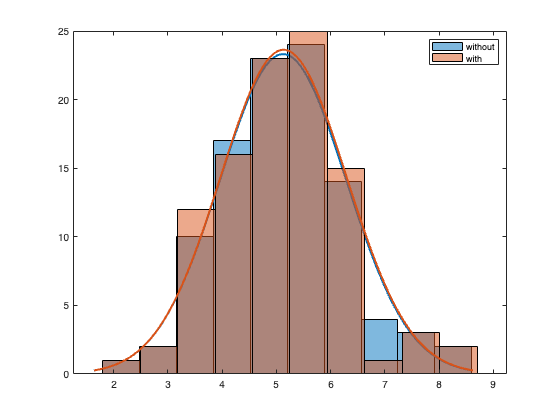

figure
cmap = colormap('lines');
h1 = histfit(Distance1);
h1(1).FaceColor = cmap(1,:);
h1(1).FaceAlpha = 0.5;
h1(2).Color = cmap(1,:);
hold on
h2 = histfit(Distance2);
h2(1).FaceColor = cmap(2,:);
h2(1).FaceAlpha = 0.5;
h2(2).Color = cmap(2,:);
legend([h1(1), h2(1)],{'without','with'})
hold off

## T-test

standard (unpaired) t-test

[~,p] = ttest2(Distance1,Distance2)

p = 0.9570

paired t-test

[~,p] = ttest(Distance1,Distance2)

p = 5.8060e-14

## ANOVA

Subject1 = categorical((1:N)');
[Chocolate1{1:N,1}] = deal('before');
Subject2 = categorical((1:N)');
[Chocolate2{1:N,1}] = deal('after');

Subject = [Subject1;Subject2];
Chocolate = [Chocolate1;Chocolate2];
Distance = [Distance1;Distance2];

Standard 1-way ANOVA

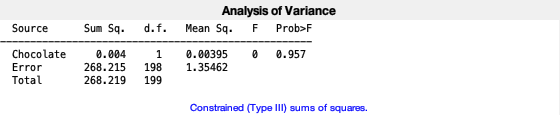

ans = 0.9570

anovan(Distance,{Chocolate},'varnames',{'Chocolate'})

2-way ANOVA with Subject as factor

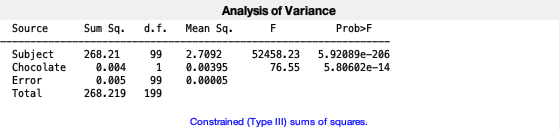

ans = 1.0e-13 *

    0.0000
    0.5806


anovan(Distance,{Subject,Chocolate},'varnames',{'Subject','Chocolate'})

## Multiple measurements per subject

M = 5; % number of measurements per subject
d = 1; % mean deviation from average in percent
Distances = NaN(2*N,M);
for m=1:M
    Distances(:,m) = Distance .* (1 + d/100*randn(2*N,1));
end
display(Distances)

Distances =     5.5505    5.5416    5.6519    5.5703    5.5438
    6.7603    6.8863    6.8333    6.7906    6.7830
    2.7534    2.7472    2.7709    2.7450    2.7782
    5.8964    5.8738    5.8434    5.9268    5.7715
    5.3674    5.3278    5.3132    5.3282    5.2291
    3.6608    3.7025    3.7117    3.6481    3.6939
    4.5919    4.5760    4.5967    4.5321    4.6258
    5.3554    5.4991    5.2901    5.3409    5.3071
    8.6665    8.4952    8.4638    8.5790    8.4867
    7.8091    7.6235    7.6822    7.7002    7.7559


What to do with the multiple measurements?

Average into one number per subject:

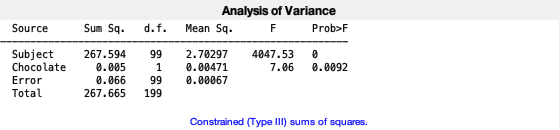

ans =     0.0000
    0.0092


anovan(mean(Distances,2),{Subject,Chocolate},'varnames',{'Subject','Chocolate'})

## Linear model

First create data tabe in long format (with observations as rows)

Data = [];
for m=1:M
 Tab = [];
 Tab.Subject = Subject;
 Tab.Trial = m*ones(2*N,1);
 Tab.Chocolate = Chocolate;
 Tab.Distance = Distances(:,m);
 Data = [Data;struct2table(Tab)];
end
% convert to categorical
Data.Subject = categorical(Data.Subject);
Data.Chocolate = categorical(Data.Chocolate);
Data.Trial = categorical(Data.Trial);
% sort by subject
Data = sortrows(Data,{'Subject','Trial'});
head(Data,18)

ans = 18×4 table
    Subject    Trial    Chocolate    Distance
    _______    _____    _________    ________

       1         1       before       5.5505 
       1         1       after        5.5729 
       1         2       before       5.5416 
       1         2       after        5.5844 
       1         3       before       5.6519 
       1         3       after         5.588 
       1         4       before       5.5703 
       1         4       after        5.5953 
       1         5       before       5.5438 
       1         5       after        5.6325 
       2         1       before       6.7603 
       2         1       after        6.8584 
       2         2       before       6.8863 
       2         2       after        6.9211 
       2         3       before       6.8333 
       2         3       after        6.7195 


% save data table to Excel file
writetable(Data,'Chocolate_LM3.xlsx');

## Random effects over subjects

formula = 'Distance ~ 1 + Chocolate + (1|Subject)'

formula = 'Distance ~ 1 + Chocolate + (1|Subject)'

mdl1 = fitlme(Data,formula)

mdl1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1000
    Fixed effects coefficients           2
    Random effects coefficients        100
    Covariance parameters                2

Formula:
    Distance ~ 1 + Chocolate + (1 | Subject)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2222.5    -2202.8    1115.2           -2230.5 

Fixed effects coefficients (95% CIs):
    Name                        Estimate      SE           tStat      DF     pValue         Lower       Upper     
    {'(Intercept)'     }            5.1325      0.11568     44.367    998    2.5796e-238      4.9055        5.3595
    {'Chocolate_before'}        -0.0097078    0.0032778    -2.9617    998      0.0031323    -0.01614    -0.0032756

Random effects covariance parameters (95% CIs):
Group: Subject (100 Levels)
    Name1          

anova(mdl1)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue     
    {'(Intercept)'}        1968.4    1      998    2.5796e-238
    {'Chocolate'  }        8.7714    1      998      0.0031323


Goodness of fit

mdl = mdl1;
RSquared = mdl.Rsquared.Ordinary

RSquared = 0.9982

Plot residuals

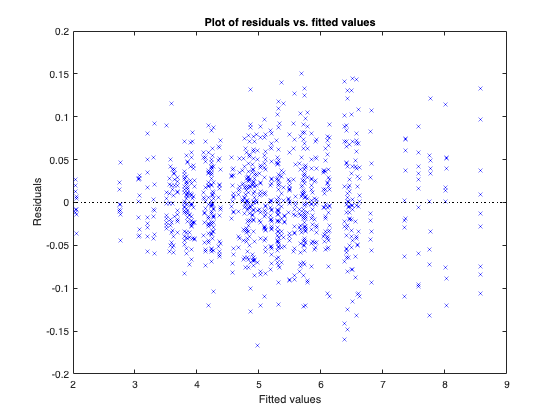

plotResiduals(mdl,'fitted');

Plot partial dependence

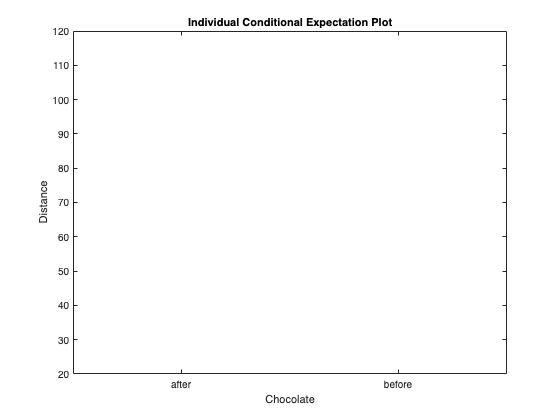

plotPartialDependence(mdl,'Chocolate','Conditional','absolute')
xlim([0.5,2.5]);
ylim([20,120]);

## Random effects over subjects and trials

formula = 'Distance ~ 1 + Chocolate + (1|Subject) + (1|Subject:Trial)'

formula = 'Distance ~ 1 + Chocolate + (1|Subject) + (1|Subject:Trial)'

mdl2 = fitlme(Data,formula)

mdl2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1000
    Fixed effects coefficients           2
    Random effects coefficients        600
    Covariance parameters                3

Formula:
    Distance ~ 1 + Chocolate + (1 | Subject) + (1 | Subject:Trial)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2220.5    -2195.9    1115.2           -2230.5 

Fixed effects coefficients (95% CIs):
    Name                        Estimate      SE           tStat      DF     pValue         Lower       Upper     
    {'(Intercept)'     }            5.1325      0.11568     44.367    998    2.5793e-238      4.9055        5.3595
    {'Chocolate_before'}        -0.0097078    0.0032778    -2.9617    998      0.0031323    -0.01614    -0.0032756

Random effects covariance parameters (95% CIs):
Group: Subject (100 Level

anova(mdl2)

ans =     ANOVA marginal tests: DFMethod = 'Residual'

    Term                   FStat     DF1    DF2    pValue     
    {'(Intercept)'}        1968.4    1      998    2.5793e-238
    {'Chocolate'  }        8.7714    1      998      0.0031323


Goodness of fit

mdl = mdl2;
RSquared = mdl.Rsquared.Ordinary

RSquared = 0.9982

Plot residuals

plotResiduals(mdl,'fitted');

Plot partial dependence

plotPartialDependence(mdl,'Chocolate','Conditional','absolute')
xlim([0.5,2.5]);
ylim([20,120]);

## Compare models

compare(mdl1,mdl2)

ans =     Theoretical Likelihood Ratio Test

    Model    DF    AIC        BIC        LogLik    LRStat        deltaDF    pValue
    mdl1     4     -2222.5    -2202.8    1115.2                                   
    mdl2     5     -2220.5    -2195.9    1115.2    -1.437e-10    1          1     


## Look at the fit results

display(mdl1)

mdl1 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1000
    Fixed effects coefficients           2
    Random effects coefficients        100
    Covariance parameters                2

Formula:
    Distance ~ 1 + Chocolate + (1 | Subject)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2222.5    -2202.8    1115.2           -2230.5 

Fixed effects coefficients (95% CIs):
    Name                        Estimate      SE           tStat      DF     pValue         Lower       Upper     
    {'(Intercept)'     }            5.1325      0.11568     44.367    998    2.5796e-238      4.9055        5.3595
    {'Chocolate_before'}        -0.0097078    0.0032778    -2.9617    998      0.0031323    -0.01614    -0.0032756

Random effects covariance parameters (95% CIs):
Group: Subject (100 Levels)
    Name1          

display(mdl2)

mdl2 = Linear mixed-effects model fit by ML

Model information:
    Number of observations            1000
    Fixed effects coefficients           2
    Random effects coefficients        600
    Covariance parameters                3

Formula:
    Distance ~ 1 + Chocolate + (1 | Subject) + (1 | Subject:Trial)

Model fit statistics:
    AIC        BIC        LogLikelihood    Deviance
    -2220.5    -2195.9    1115.2           -2230.5 

Fixed effects coefficients (95% CIs):
    Name                        Estimate      SE           tStat      DF     pValue         Lower       Upper     
    {'(Intercept)'     }            5.1325      0.11568     44.367    998    2.5793e-238      4.9055        5.3595
    {'Chocolate_before'}        -0.0097078    0.0032778    -2.9617    998      0.0031323    -0.01614    -0.0032756

Random effects covariance parameters (95% CIs):
Group: Subject (100 Level